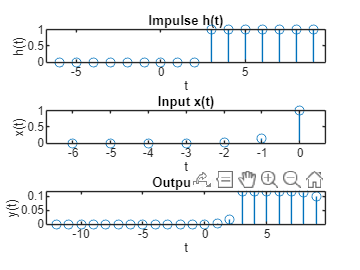

% time range
h_t = -6:9;
x_t = -6:0;

h_n = (h_t >= 3);


x_n = exp(2 * x_t);

% convolution
y = conv(h_n, x_n) * 0.1;
t_y = h_t(1) + x_t(1) : h_t(end) + x_t(end);

% Plotting
figure;

% Impulse response
subplot(3, 1, 1);
stem(h_t, h_n);
title('Impulse h(t)');
xlabel('t');
ylabel('h(t)');

% Inpute signals
subplot(3, 1, 2);
stem(x_t, x_n);
title('Input x(t)');
xlabel('t');
ylabel('x(t)');

% output
subplot(3, 1, 3);
stem(t_y, y);
title('Output y(t)');
xlabel('t');
ylabel('y(t)');